% Define the data for lower limit, upper limit, and frequency
lowerLimits = [80,85,90,95,100,105,110,115,120,125,130,135,140,145,150]; 
upperLimits = [85,90,95,100,105,110,115,120,125,130,135,140,145,150,155]; 
frequencies = [21,29,19,39,43,94,73,68,36,45,27,48,21,12,5];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        80            85           21    
        85            90           29    
        90            95           19    
        95           100           39    
       100           105           43    
       105           110           94    
       110           115           73    
       115           120           68    
       120           125           36    
       125           130           45    
       130           135           27    
       135           140           48    
       140           145           21    
       145           150           12    
       150           155            5    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 114.47


fprintf('Median: %.2f\n', medianValue);

Median: 112.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 107.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 16.39


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 108.55


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -1.05


fprintf('Karl: %.2f\n', Karl);

Karl: 0.43


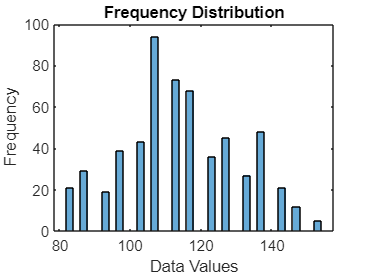


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');